Esercizio 3 - FFT su segnale 2D: aggiunta rumore, analisi e filtraggio

Lettura immagine

x = imread('Diego-Armando-Maradona.jpg');
x = double(rgb2gray(x)) ./ 255;

Aggiunta del rumore sinusoidale e visualizzazione

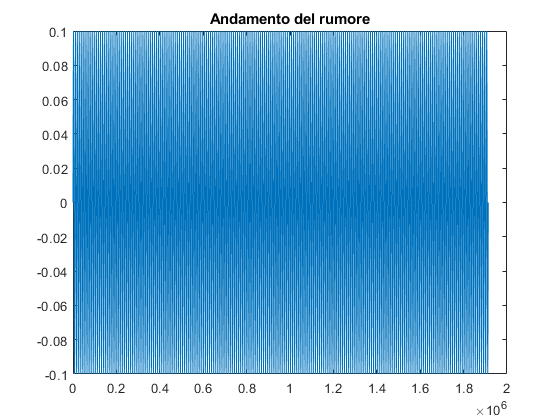

d = size(x(:));
freq = 200;
n_x = linspace(0, d(1), d(1)); % potrei metterli tra 0 ed 1 ma così riduco gli errori di calcolo
alfa = 0.1;
n = alfa .* sin(2 * pi / d(1) * freq * n_x);
figure(); plot(n_x, n); title('Andamento del rumore');

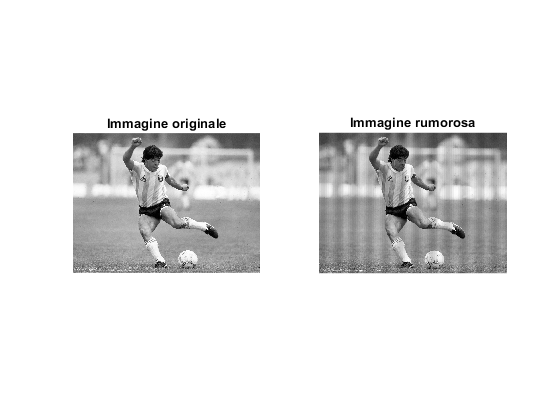

n = reshape(n, size(x));
y = x + x .* n;
y = y + abs(min(y(:)));
y = y ./ max(y(:));
figure();
subplot(1,2,1); imshow(x); title('Immagine originale');
subplot(1,2,2); imshow(y); title('Immagine rumorosa');

Analisi in frequenza

[M, N] = size(y);
Y = fftshift(fft2(y,M,N));
n = (-0.5):1/N:(0.5-1/N);
m = (-0.5):1/M:(0.5-1/M);
[l, k] = meshgrid(n, m);
figure();
subplot(2,2,1); imshow(log(abs(Y)+1), [], 'XData', n, 'YData', m); axis('on');
title('Immagine rumorosa in frequenza');
subplot(2,2,3); mesh(l, k, log(abs(Y)+1));

Filtraggio in frequenza e tuning del filtro

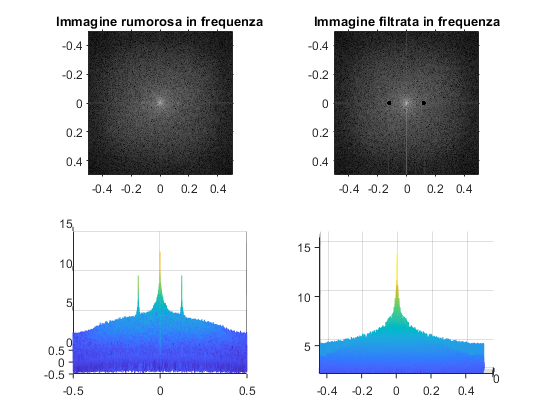

dist = @(l, k, l0, k0) sqrt( (l-l0).^2 + (k-k0).^2 );
d1 = dist(l, k, 0.12, 0);
d2 = dist(l, k, -0.12, 0);
th = 0.015;
H = (d1 > th) & (d2 > th);
subplot(2,2,2); imshow(log(abs(Y).*H + 1), [], 'XData', n, 'YData', m); axis('on');
title('Immagine filtrata in frequenza');
subplot(2,2,4); mesh(l, k, log(abs(Y).*H+1));

F = Y .* H;

Ritorno nel dominio del tempo e visualizzo il risultato

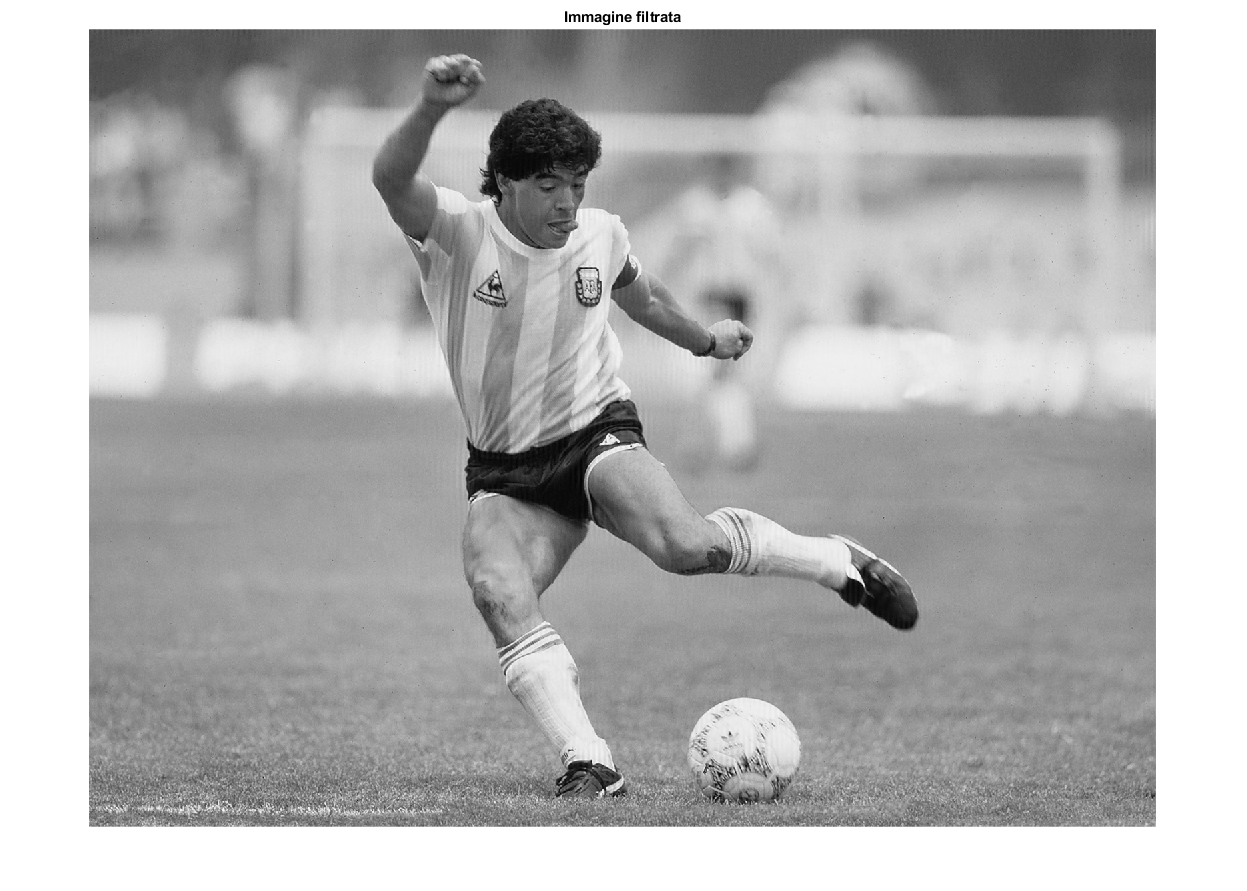

f = real(ifft2(ifftshift(F)));
figure();
imshow(f, []); title('Immagine filtrata'); 

Valutazione dell'errore quadratico medio

f = f + abs(min(f(:)));
f = f ./ max(f(:));
mse_noisy = immse(x, y)

mse_noisy = 0.0055

mse_filtered = immse(x, f)

mse_filtered = 0.0012